% 准备区
clear;
clc;

addpath(genpath('utils'));
load('.\data\filtering_data_no_downsampling.mat');
load('data\regression_matrix_num_no_downsampling.mat');
load('data\base_parameters_identified_tmp.mat');

g = 9.80665;
[n_sample, ~] = size(q_filt);
T = zeros(n_sample, 7);
T_idy = zeros(n_sample, 7);

for k = 1 : 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);
    T(k, :) = t_filt(k, :);
    ww = compute_regression_matrix(q, qd, qdd);

    T_idy(k,:) = ww * P;
    fprintf('完成第%d帧数据的计算\n', k);
end

完成第1帧数据的计算
完成第2帧数据的计算
完成第3帧数据的计算
完成第4帧数据的计算
完成第5帧数据的计算
完成第6帧数据的计算
完成第7帧数据的计算
完成第8帧数据的计算
完成第9帧数据的计算
完成第10帧数据的计算
完成第11帧数据的计算
完成第12帧数据的计算
完成第13帧数据的计算
完成第14帧数据的计算
完成第15帧数据的计算
完成第16帧数据的计算
完成第17帧数据的计算
完成第18帧数据的计算
完成第19帧数据的计算
完成第20帧数据的计算
完成第21帧数据的计算
完成第22帧数据的计算
完成第23帧数据的计算
完成第24帧数据的计算
完成第25帧数据的计算
完成第26帧数据的计算
完成第27帧数据的计算
完成第28帧数据的计算
完成第29帧数据的计算
完成第30帧数据的计算
完成第31帧数据的计算
完成第32帧数据的计算
完成第33帧数据的计算
完成第34帧数据的计算
完成第35帧数据的计算
完成第36帧数据的计算
完成第37帧数据的计算
完成第38帧数据的计算
完成第39帧数据的计算
完成第40帧数据的计算
完成第41帧数据的计算
完成第42帧数据的计算
完成第43帧数据的计算
完成第44帧数据的计算
完成第45帧数据的计算
完成第46帧数据的计算
完成第47帧数据的计算
完成第48帧数据的计算
完成第49帧数据的计算
完成第50帧数据的计算
完成第51帧数据的计算
完成第52帧数据的计算
完成第53帧数据的计算
完成第54帧数据的计算
完成第55帧数据的计算
完成第56帧数据的计算
完成第57帧数据的计算
完成第58帧数据的计算
完成第59帧数据的计算
完成第60帧数据的计算
完成第61帧数据的计算
完成第62帧数据的计算
完成第63帧数据的计算
完成第64帧数据的计算
完成第65帧数据的计算
完成第66帧数据的计算
完成第67帧数据的计算
完成第68帧数据的计算
完成第69帧数据的计算
完成第70帧数据的计算
完成第71帧数据的计算
完成第72帧数据的计算
完成第73帧数据的计算
完成第74帧数据的计算
完成第75帧数据的计算
完成第76帧数据的计算
完成第77帧数据的计算
完成第78帧数据的计算
完成第79帧数据的计算
完成第80帧数据的计算
完成第81帧数据的计算
完成第82帧数据的计算
完成第83帧数据的计算
完成第84帧数据的计算
完

save('data\T_from_inverse_dynamic_model_no_downsampling.mat', "T_idy");

## VISUALIZATION

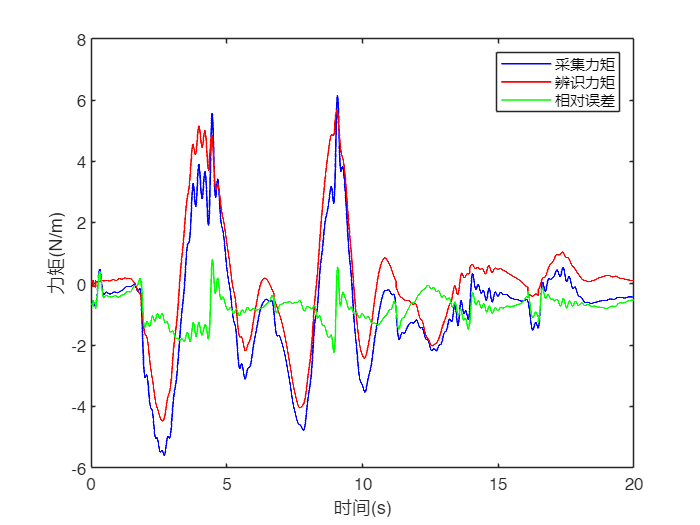

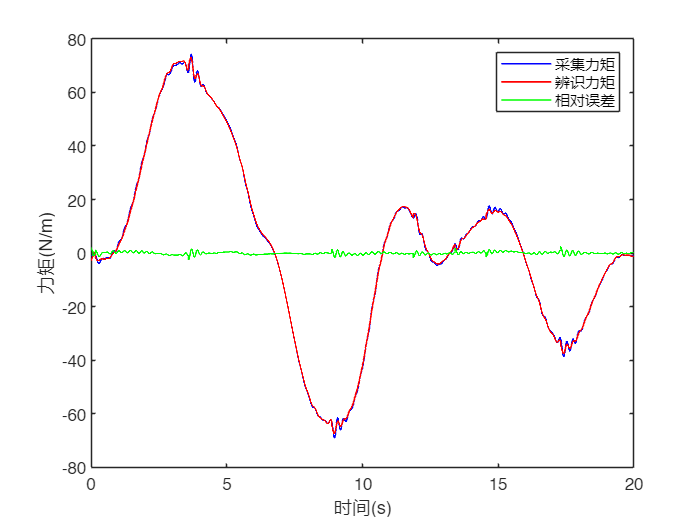

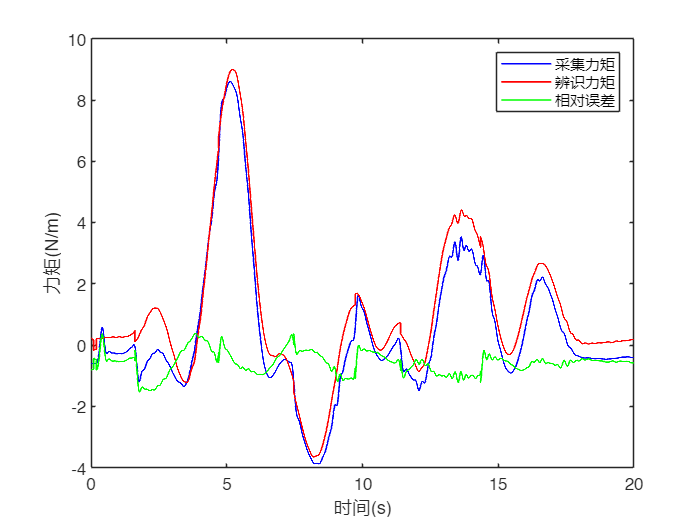

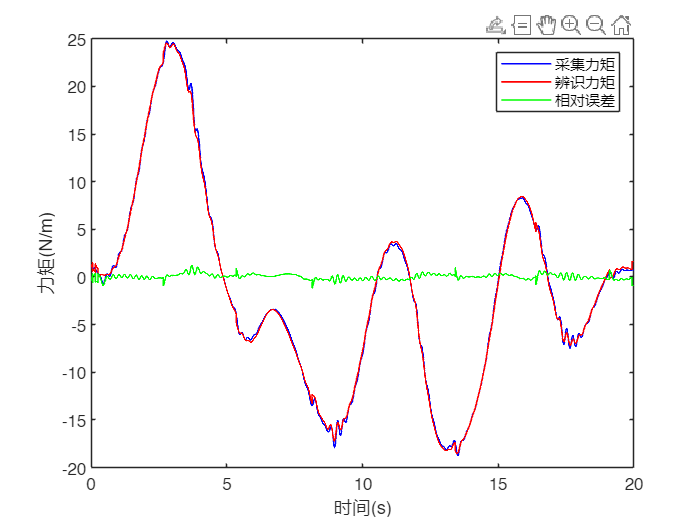

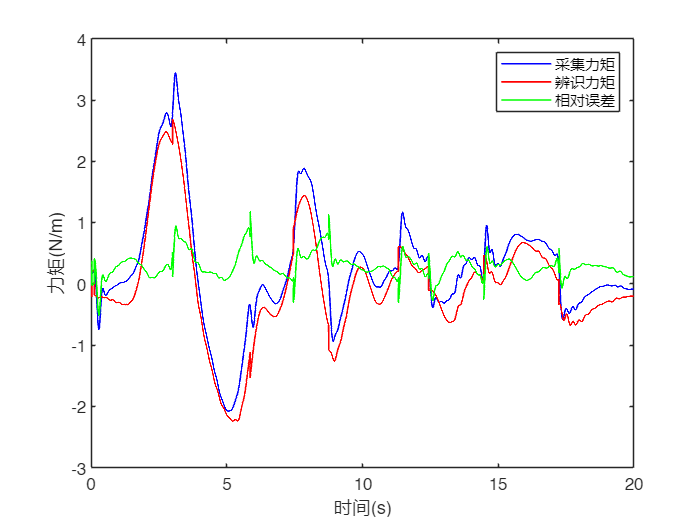

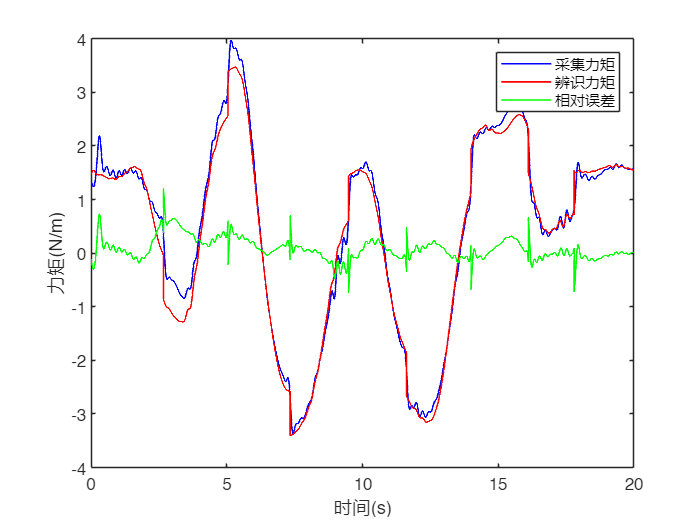

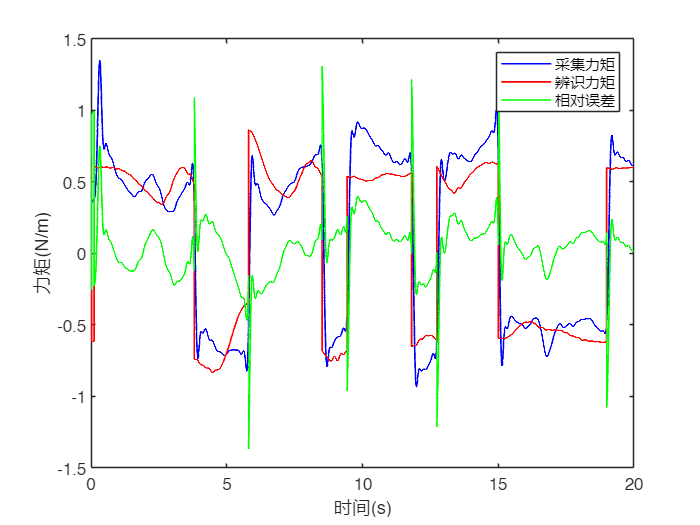

traj_Ts = 0.001;

t = linspace(0, n_sample - 1, n_sample) * traj_Ts;

for ii = 1:7
    figure(ii);
    plot(t, T(:, ii), 'b', 'LineWidth', 1.0); hold on;
    plot(t, T_idy(:, ii), 'r', 'LineWidth', 1.0);
    plot(t, T(:, ii) - T_idy(:, ii), 'g', 'LineWidth', 1.0); hold off;
    ylabel('力矩(N/m)');
    xlabel('时间(s)');
    legend('采集力矩', '辨识力矩', '相对误差')
    % title(['第', num2str(ii), '关节辨识参数验证'])
end


% for jj = 1:7
%     figure(jj + 7);
%     plot(t, T(:, jj) - T_idy(:, jj), 'g', 'LineWidth', 1.0);
%     title(['第', num2str(jj), '关节辨识参数误差']);
%     ylabel('力矩(Nm)')
%     % print(7 + jj, '-dpng', '-r600', ['.\figs\diff\diff', num2str(jj), '.png']);
% end
% 
% error = zeros(7, 1);
% figure(15)
% for kk = 1:7
%     plot(t, T(:, kk) - T_idy(:, kk), 'LineWidth', 1.0); hold on;
%     error(kk) = sum((T(:, kk) - T_idy(:, kk)).^2);
% end
% 
% ylabel('力矩(Nm)');
% legend('关节1', '关节2', '关节3', '关节4', '关节5', '关节6', '关节7')
% title('辨识力矩与采集力矩误差')
% % print(15, '-dpng', '-r600', '.\figs\holistic_diff.png');
% 
% disp('Identification error for 7 joints:');
% disp(sqrt(error / 200));